clear all;
clc

### Reading data

Data20F     = readtable('Data.csv');
startDate   = datenum('08-03-2017');  % This is the first day in our sample
endDate     = datenum('01-31-2023');  % This is the last day in our sample
xData       = linspace(startDate, endDate, height(Data20F(end-1382:end,1)));
xData       = datenum(xData);

benchmark    = table2array(Data20F(end-1382:end,2));
factors      = table2array(Data20F(end-1382:end,4:23));

### Defining key functions for portfolio construction

% Here we compute the optimal weights of factors

function theta = calculate_theta(benchmark, factors, M, np, gam)

    T   = size(benchmark, 1);    % Total lenght
    nf  = size(factors, 2);      % Defining the number of factors
    B   = 0.8;                   % B measures how much in terms of the wealth is invested in factors

    % We are using a third dimension to save our portoflios
    theta   = NaN(nf, T-M, np);  % 3D array for factor weights
    
    X0  = 0 * ones(nf, 1);
    A   = ones(1, nf);
    Aeq = [];
    Beq = [];
    LB  = zeros(1, nf);
    UB  = Inf(1, nf);
    
    warning off
    options = optimoptions('fmincon', 'Display', 'off', 'Algorithm', 'sqp');
    
    for i = 1:T-M
        
        t0  = i;
        t   = M + i - 1;
        
        benchmark_est = benchmark(t0:t);
        factors_est = factors(t0:t, :);
    
        % Mean variance portfolio.
        mean_var        = @(theta) - (mean(benchmark_est + factors_est * theta) ...
                                 - gam/2 * std(benchmark_est + factors_est * theta));
        theta(:, i, 1)  = fmincon(mean_var, X0, A, B, Aeq, Beq, LB, UB, [], options);
                
        % Minimum variance portfolio.
        min_var         = @(theta) std(benchmark_est + factors_est * theta);
        theta(:, i, 4)  = fmincon(min_var, X0, A, B, Aeq, Beq, LB, UB, [], options);

        % Bayes–Stein mean variance portfolio (mean shrinkage).
        % We use average return on sample minimum variance
        % portfolio (u_min_t) as a target.
        u_t = mean([benchmark_est, factors_est], 1)';
        u_min_t = mean([benchmark_est, factors_est], 1) * vertcat(1, reshape(theta(:, i, 4), [], 1));
        sigma = cov([benchmark_est, factors_est]);
        rho = (nf+3) / ( (nf+3) + M*(u_t - u_min_t)' * inv(sigma) * (u_t - u_min_t) );
        mean_hat = (1-rho) * u_t + rho * u_min_t;
        bs_mean_var = @(theta) - (mean_hat' * vertcat(1, theta) ...
                                   - gam/2 * std(benchmark_est + factors_est * theta));
        theta(:, i, 2)  = fmincon(bs_mean_var, X0, A, B, Aeq, Beq, LB, UB, [], options);

        % Ledoit-Wolf mean variance portfolio (covariance shrinkage).
        %rho = 0.5;
        sigma_hat = covarianceShrinkage([benchmark_est, factors_est]);
        %sigma_hat = (1-rho) * sigma + rho * mean(diag(sigma)) * eye(nf+1);
        lw_mean_var = @(theta) - (mean(benchmark_est + factors_est * theta) ...
                                   - gam/2 * sqrt(vertcat(1, theta)' * sigma_hat * vertcat(1, theta)) );
        theta(:, i, 3)  = fmincon(lw_mean_var, X0, A, B, Aeq, Beq, LB, UB, [], options);
        
        % CVar portfolio.
        theta(:, i, 5)  = CVaR(benchmark_est, factors_est, B, 0.05);

        % Naive portfolio.
        theta(:, i, 6)  = B / nf;
        
    end

end

function rp = calculate_returns(benchmark, factors, theta, M, np, include_tc)

    T    = size(benchmark, 1);  % Total lenght
    kapa = (50/10000)/21;       % Proportional transactions cost
    rp   = NaN(T-M, np);
    
    if include_tc == 0

        for portfolio = 1:np
            rp(:, portfolio) = ( benchmark(M+1:end,:) ...
                                 + sum(squeeze(theta(:,:,portfolio))'.*factors(M+1:end,:), 2) );
        end

    elseif include_tc == 1
        
        for portfolio = 1:np

            % We assume that portfolio formation (in the first period) has no cost
            rp(1,portfolio) = benchmark(M+1,:) + factors(M+1,:) * theta(:,1,portfolio) - kapa*0;

            for itime = 2:T-M
                w1      = theta(:, itime-1, portfolio)';
                w2      = theta(:, itime  , portfolio)';
                if sum((1+factors(M+itime-1,:)).*w1) ~= 0
                    w1 = ((1+factors(M+itime-1,:)).*w1) ./ sum((1+factors(M+itime-1,:)).*w1);
                elseif sum((1+factors(M+itime-1,:)).*w1) == 0
                    w1 = zeros(size(factors,2), 1)';
                end
                turnvec = sum(abs(w2-w1),2);
                rp(itime,portfolio) = ( benchmark(M+itime,:) ...
                                        + factors(M+itime,:) * theta(:,itime,portfolio) - kapa*turnvec);
                clear turnvec
            end

        end

    end
end

% Here we compute Ulcer index

function ulcer_index = calculate_ulcer_index(rp)

    cumulative_rp = exp(cumsum(log(1+rp)));
    cumulative_max = cummax(cumulative_rp);
    drawdowns = (cumulative_max - cumulative_rp) ./ cumulative_max;
    ulcer_index = sqrt(mean(drawdowns .^ 2));

end

% Now we compute the sharpe ratios and other performance
% measures of our portfolio strategies

function calculate_metrics(rp)

    portfolio_names = {'Mean-variance portfolio';
                       'BS Mean-variance portfolio';
                       'LW Mean-variance portfolio';
                       'Minimum-variance portfolio';
                       'CVaR portfolio';
                       '1/N portfolio'};
    
    for p_num = 1:length(portfolio_names)
        
        MN    = mean(rp(:,p_num)) * 252;
        SD    = std(rp(:,p_num)) *sqrt(252);
        SR    = (mean(rp(:,p_num))/std(rp(:,p_num))) *sqrt(252);
        MDD   = maxdrawdown(exp(cumsum(log(1+rp(:,p_num)))));
        UI    = calculate_ulcer_index(rp(:,p_num)) *sqrt(252);
        SW    = skewness(rp(:,p_num));
        
        fprintf(['-----' portfolio_names{p_num} '-----\n'])
        fprintf('Mean = %4.3f \n', MN)
        fprintf('Std = %4.3f \n', SD)
        fprintf('Sharpe ratio = %4.3f \n', SR)
        fprintf('MDD = %4.3f \n', MDD)
        fprintf('UI = %4.3f \n', UI)
        fprintf('Skewness = %4.3f \n', SW)

    end

end

% Here we define a function that computes and plots 
% the cumulative returns of the portfolio

function plot_comulative_returns(xData, r_benchmark, rp_with_factors, M, name)

    figure;
    plot(xData(M+1:end), exp(cumsum(log(1+r_benchmark))), 'LineWidth', 1.5);
    hold on
    plot(xData(M+1:end), exp(cumsum(log(1+rp_with_factors(:,1)))),'-m', 'LineWidth', 1.5)
    plot(xData(M+1:end), exp(cumsum(log(1+rp_with_factors(:,2)))),'-b', 'LineWidth', 1.5)
    plot(xData(M+1:end), exp(cumsum(log(1+rp_with_factors(:,3)))),'-r', 'LineWidth', 1.5)
    plot(xData(M+1:end), exp(cumsum(log(1+rp_with_factors(:,4)))),'-y', 'LineWidth', 1.5)
    plot(xData(M+1:end), exp(cumsum(log(1+rp_with_factors(:,5)))),'-k', 'LineWidth', 1.5)
    plot(xData(M+1:end), exp(cumsum(log(1+rp_with_factors(:,6)))),'-g', 'LineWidth', 1.5)
    datetick('x', 'yyyy', 'keeplimits')
    recessionplot
    axis([xData(M+1) xData(end) -inf inf])
    xlabel('Years');
    ylabel('Wealth of an investor, $')
    title(append('Portfolio Returns: ', name))
    p_names = {'Market';
               'Mean Variance';
               'BS Mean Variance';
               'LW Mean Variance';
               'Minimum Variance';
               'CVaR';
               'Naive portfolio'};
    legend(p_names, 'Location', 'Northwest', 'FontSize', 8)

end

% Defining function for plotting the dynamics of factor weights

function plot_factor_thetas(xData, factor_names, port_names, np, theta, M, name)
    
    figure;
    tiledlayout(3, 2, 'TileSpacing', 'Compact', 'Padding', 'Compact');
    for p = 1:np
        factor_num = size(factor_names, 1);
        y = zeros(factor_num, size(xData(M+1:end), 2));
        for i = 1:factor_num
            y(i, :) = theta(i,:,p);
        end
        nexttile
        area(xData(M+1:end), y', 'LineWidth', 1);
        hold on
        datetick('x','yyyy','keeplimits')
        recessionplot
        axis([xData(M+1) xData(end) -inf inf])
        xlabel('Years');
        ylabel('Share of total wealth')
        title([name, port_names(p), ' Portfolio'])
    end
    legend(factor_names, 'Location', 'best', 'FontSize', 8)

end

M           = 252;   % Defining the estimation window equal to 1 year of data
np          = 6;     % Defining the number of policies
gam         = 1;     % Investor's risk aversion level
trans_costs = 1;     % 1 if transaction costs are included and 0 if they are not

port_names = [{'Mean Variance'};
              {'BS Mean Variance'};
              {'LW Mean Variance'};
              {'Minimum Variance'};
              {'CVaR'};
              {'Naive'}];

equity_factor_names = [{'SMB'};
                       {'HML'};
                       {'RMV'};
                       {'CMA'};
                       {'MOM'};
                       {'ST REV'};
                       {'LT REV'}];

crypto_factor_names = [{'Twitter followers'};
                       {'Marketcap'};
                       {'BM'};
                       {'Max30'};
                       {'r30 0'};
                       {'rvol30'}];

currency_factor_names = [{'CAR'};
                         {'MOM1'};
                         {'MOM3'};
                         {'MOM6'};
                         {'MOM12'};
                         {'VOL'};
                         {'VRP'}];

r_benchmark  = benchmark(M+1:end, :);
MNbenchmark  = mean(r_benchmark) * 252;
SDbenchmark  = std(r_benchmark) *sqrt(252);
SRbenchmark  = MNbenchmark / SDbenchmark;
MDDbenchmark = maxdrawdown(exp(cumsum(log(1+r_benchmark))));
UIbenchmark  = calculate_ulcer_index(r_benchmark) *sqrt(252);

fprintf('-----Metrics for benchmark-----\n')

-----Metrics for benchmark-----


fprintf('Mean = %4.3f \n', MNbenchmark)

Mean = 0.106 


fprintf('Std = %4.3f \n', SDbenchmark)

Std = 0.230 


fprintf('Sharpe ratio = %4.3f \n', SRbenchmark)

Sharpe ratio = 0.462 


fprintf('MDD = %4.3f \n', MDDbenchmark)

MDD = 0.343 


fprintf('UI = %4.3f \n', UIbenchmark)

UI = 1.646 


### Constructing factor-based portfolios

#### Using only equity factors

equity_factors = factors(end-1382:end, 1:7);
theta_equity = calculate_theta(benchmark, equity_factors, M, np, gam);
rp_equity = calculate_returns(benchmark, equity_factors, theta_equity, M, np, trans_costs);
calculate_metrics(rp_equity);

-----Mean-variance portfolio-----
Mean = 0.081 
Std = 0.219 
Sharpe ratio = 0.372 
MDD = 0.329 
UI = 1.496 
Skewness = -0.771 
-----BS Mean-variance portfolio-----
Mean = 0.094 
Std = 0.218 
Sharpe ratio = 0.429 
MDD = 0.329 
UI = 1.430 
Skewness = -0.740 
-----LW Mean-variance portfolio-----
Mean = 0.078 
Std = 0.218 
Sharpe ratio = 0.357 
MDD = 0.327 
UI = 1.481 
Skewness = -0.757 
-----Minimum-variance portfolio-----
Mean = 0.093 
Std = 0.217 
Sharpe ratio = 0.426 
MDD = 0.352 
UI = 1.487 
Skewness = -0.779 
-----CVaR portfolio-----
Mean = 0.185 
Std = 0.280 
Sharpe ratio = 0.662 
MDD = 0.303 
UI = 1.675 
Skewness = 0.915 
-----1/N portfolio-----
Mean = 0.114 
Std = 0.235 
Sharpe ratio = 0.486 
MDD = 0.383 
UI = 1.399 
Skewness = -0.648 


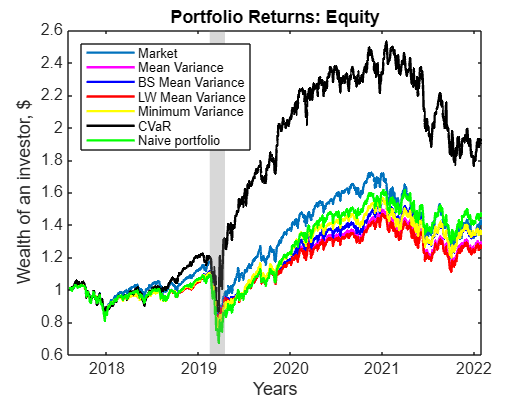

plot_comulative_returns(xData, r_benchmark, rp_equity, M, 'Equity');

#### Using only currency factors

currency_factors = factors(end-1382:end, 8:14);
theta_currency = calculate_theta(benchmark, currency_factors, M, np, gam);
rp_currency = calculate_returns(benchmark, currency_factors, theta_currency, M, np, trans_costs);
calculate_metrics(rp_currency);

-----Mean-variance portfolio-----
Mean = 0.092 
Std = 0.212 
Sharpe ratio = 0.435 
MDD = 0.279 
UI = 1.876 
Skewness = -0.580 
-----BS Mean-variance portfolio-----
Mean = 0.096 
Std = 0.211 
Sharpe ratio = 0.453 
MDD = 0.275 
UI = 1.811 
Skewness = -0.571 
-----LW Mean-variance portfolio-----
Mean = 0.089 
Std = 0.212 
Sharpe ratio = 0.422 
MDD = 0.289 
UI = 1.911 
Skewness = -0.587 
-----Minimum-variance portfolio-----
Mean = 0.103 
Std = 0.212 
Sharpe ratio = 0.488 
MDD = 0.271 
UI = 1.695 
Skewness = -0.517 
-----CVaR portfolio-----
Mean = 0.040 
Std = 0.267 
Sharpe ratio = 0.151 
MDD = 0.430 
UI = 2.545 
Skewness = -0.809 
-----1/N portfolio-----
Mean = 0.113 
Std = 0.240 
Sharpe ratio = 0.470 
MDD = 0.382 
UI = 1.785 
Skewness = -0.747 


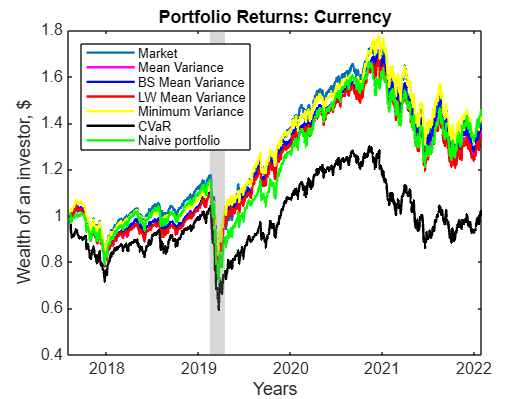

plot_comulative_returns(xData, r_benchmark, rp_currency, M, 'Currency');

#### Using only cryptocurrency factors

crypto_factors = factors(end-1382:end, 15:20);
theta_crypto = calculate_theta(benchmark, crypto_factors, M, np, gam);
rp_crypto = calculate_returns(benchmark, crypto_factors, theta_crypto, M, np, trans_costs);
calculate_metrics(rp_crypto);

-----Mean-variance portfolio-----
Mean = 0.660 
Std = 0.302 
Sharpe ratio = 2.184 
MDD = 0.360 
UI = 1.330 
Skewness = 0.493 
-----BS Mean-variance portfolio-----
Mean = 0.499 
Std = 0.275 
Sharpe ratio = 1.817 
MDD = 0.356 
UI = 1.483 
Skewness = 0.036 
-----LW Mean-variance portfolio-----
Mean = 1.095 
Std = 0.438 
Sharpe ratio = 2.497 
MDD = 0.406 
UI = 1.789 
Skewness = 3.337 
-----Minimum-variance portfolio-----
Mean = 0.148 
Std = 0.231 
Sharpe ratio = 0.640 
MDD = 0.348 
UI = 1.736 
Skewness = -0.540 
-----CVaR portfolio-----
Mean = 2.408 
Std = 0.918 
Sharpe ratio = 2.623 
MDD = 0.649 
UI = 3.740 
Skewness = 1.490 
-----1/N portfolio-----
Mean = 1.254 
Std = 0.412 
Sharpe ratio = 3.044 
MDD = 0.337 
UI = 1.262 
Skewness = 2.029 


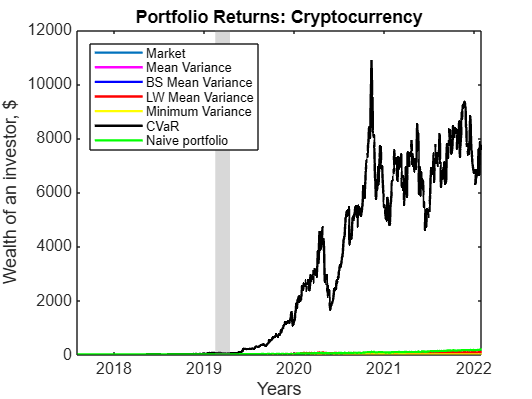

plot_comulative_returns(xData, r_benchmark, rp_crypto, M, 'Cryptocurrency');

#### Using equity and currency factors

equity_currency_factors = factors(end-1382:end, 1:14);
theta_equity_currency = calculate_theta(benchmark, equity_currency_factors, M, np, gam);
rp_equity_currency = calculate_returns(benchmark, equity_currency_factors, ...
                                       theta_equity_currency, M, np, trans_costs);
calculate_metrics(rp_equity_currency);

-----Mean-variance portfolio-----
Mean = 0.099 
Std = 0.206 
Sharpe ratio = 0.482 
MDD = 0.283 
UI = 1.559 
Skewness = -0.816 
-----BS Mean-variance portfolio-----
Mean = 0.103 
Std = 0.205 
Sharpe ratio = 0.504 
MDD = 0.280 
UI = 1.517 
Skewness = -0.784 
-----LW Mean-variance portfolio-----
Mean = 0.095 
Std = 0.206 
Sharpe ratio = 0.460 
MDD = 0.286 
UI = 1.563 
Skewness = -0.799 
-----Minimum-variance portfolio-----
Mean = 0.107 
Std = 0.203 
Sharpe ratio = 0.527 
MDD = 0.280 
UI = 1.486 
Skewness = -0.721 
-----CVaR portfolio-----
Mean = 0.095 
Std = 0.286 
Sharpe ratio = 0.331 
MDD = 0.430 
UI = 2.124 
Skewness = -0.184 
-----1/N portfolio-----
Mean = 0.114 
Std = 0.235 
Sharpe ratio = 0.482 
MDD = 0.382 
UI = 1.542 
Skewness = -0.723 


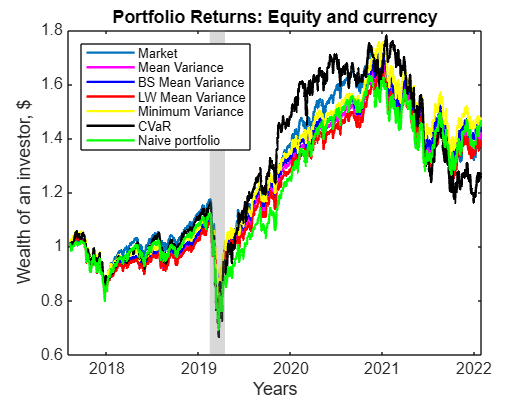

plot_comulative_returns(xData, r_benchmark, rp_equity_currency, M, 'Equity and currency');

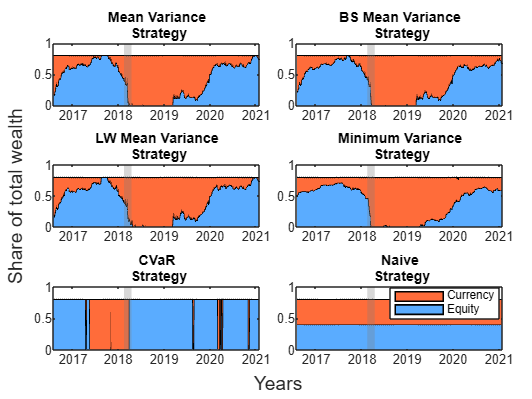

figure
t = tiledlayout(3, 2, 'TileSpacing', 'Compact', 'Padding', 'Compact');
for p = 1:np
    y1 = sum(theta_equity_currency(1:7,:,p), 1);
    y2 = sum(theta_equity_currency(8:14,:,p), 1);
    nexttile
    area(xData(M+1:end), [y1; y2]', 'LineWidth', 1);
    hold on
    datetick('x','yyyy','keeplimits')
    recessionplot
    axis([xData(M+1) xData(end) -inf inf])
    colororder(['#5AACFF'; '#FF6C3A'])
    xlabel(t, 'Years');
    ylabel(t, 'Share of total wealth')
    title([port_names(p), ' Strategy'])
end
legend('Equity', 'Currency', 'Location', 'best')

#### Using equity and cryptocurrency factors

equity_crypto_factors = factors(end-1382:end, [1:7, 15:20]);
theta_equity_crypto = calculate_theta(benchmark, equity_crypto_factors, M, np, gam);
rp_equity_crypto = calculate_returns(benchmark, equity_crypto_factors, ...
                                     theta_equity_crypto, M, np, trans_costs);
calculate_metrics(rp_equity_crypto);

-----Mean-variance portfolio-----
Mean = 0.603 
Std = 0.282 
Sharpe ratio = 2.139 
MDD = 0.341 
UI = 1.082 
Skewness = 0.588 
-----BS Mean-variance portfolio-----
Mean = 0.512 
Std = 0.265 
Sharpe ratio = 1.934 
MDD = 0.336 
UI = 1.175 
Skewness = 0.354 
-----LW Mean-variance portfolio-----
Mean = 0.856 
Std = 0.360 
Sharpe ratio = 2.382 
MDD = 0.381 
UI = 1.409 
Skewness = 2.243 
-----Minimum-variance portfolio-----
Mean = 0.160 
Std = 0.218 
Sharpe ratio = 0.736 
MDD = 0.349 
UI = 1.348 
Skewness = -0.773 
-----CVaR portfolio-----
Mean = 2.414 
Std = 0.918 
Sharpe ratio = 2.628 
MDD = 0.649 
UI = 3.685 
Skewness = 1.488 
-----1/N portfolio-----
Mean = 0.640 
Std = 0.277 
Sharpe ratio = 2.309 
MDD = 0.360 
UI = 0.934 
Skewness = 0.370 


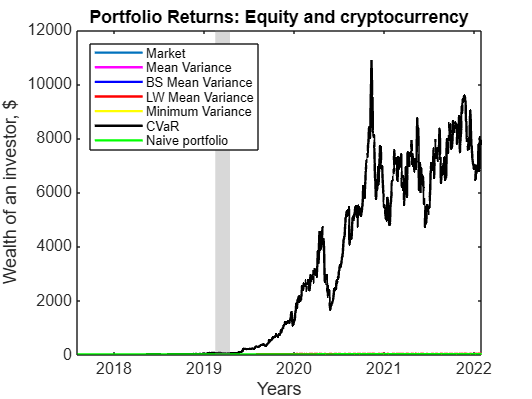

plot_comulative_returns(xData, r_benchmark, rp_equity_crypto, M, 'Equity and cryptocurrency');

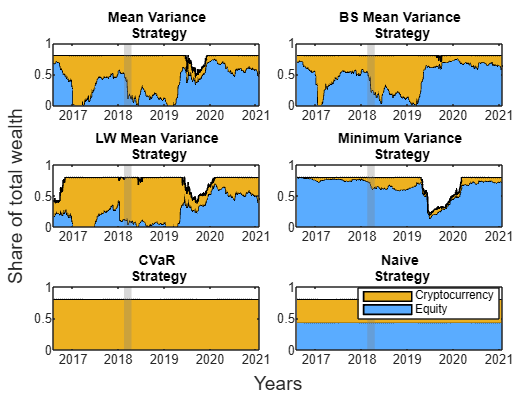

figure;
t = tiledlayout(3, 2, 'TileSpacing', 'Compact', 'Padding', 'Compact');
for p = 1:np
    y1 = sum(theta_equity_crypto(1:7,:,p), 1);
    y2 = sum(theta_equity_crypto(8:13,:,p), 1);
    nexttile
    area(xData(M+1:end), [y1; y2]', 'LineWidth', 1);
    hold on
    datetick('x','yyyy','keeplimits')
    recessionplot
    axis([xData(M+1) xData(end) -inf inf])
    colororder(['#5AACFF'; '#EDB120'])
    xlabel(t, 'Years');
    ylabel(t, 'Share of total wealth')
    title([port_names(p), ' Strategy'])
end
legend('Equity', 'Cryptocurrency', 'Location', 'best')

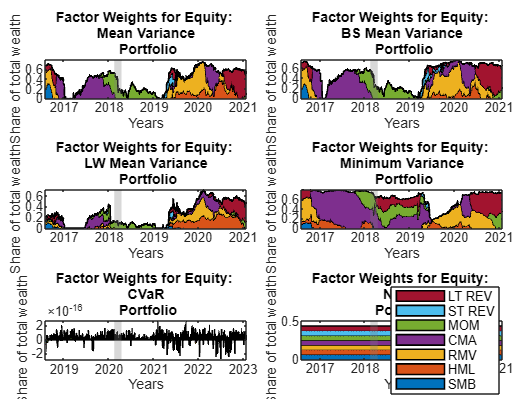

plot_factor_thetas(xData, equity_factor_names, port_names, ...
                       np, theta_equity_crypto(1:7,:,:), M, 'Factor Weights for Equity: ')

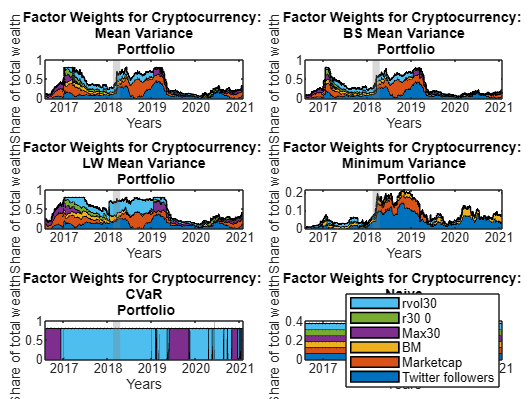

plot_factor_thetas(xData, crypto_factor_names, port_names, ...
                       np, theta_equity_crypto(8:13,:,:), M, 'Factor Weights for Cryptocurrency: ')

#### Using currency and cryptocurrency factors

currency_crypto_factors = factors(end-1382:end, 8:20);
theta_currency_crypto = calculate_theta(benchmark, currency_crypto_factors, M, np, gam);
rp_currency_crypto = calculate_returns(benchmark, currency_crypto_factors, ...
                                       theta_currency_crypto, M, np, trans_costs);
calculate_metrics(rp_currency_crypto);

-----Mean-variance portfolio-----
Mean = 0.572 
Std = 0.278 
Sharpe ratio = 2.059 
MDD = 0.336 
UI = 1.275 
Skewness = 0.328 
-----BS Mean-variance portfolio-----
Mean = 0.456 
Std = 0.254 
Sharpe ratio = 1.799 
MDD = 0.318 
UI = 1.423 
Skewness = -0.119 
-----LW Mean-variance portfolio-----
Mean = 0.860 
Std = 0.362 
Sharpe ratio = 2.374 
MDD = 0.386 
UI = 1.634 
Skewness = 1.957 
-----Minimum-variance portfolio-----
Mean = 0.143 
Std = 0.212 
Sharpe ratio = 0.675 
MDD = 0.277 
UI = 1.591 
Skewness = -0.583 
-----CVaR portfolio-----
Mean = 2.408 
Std = 0.918 
Sharpe ratio = 2.623 
MDD = 0.649 
UI = 3.740 
Skewness = 1.490 
-----1/N portfolio-----
Mean = 0.640 
Std = 0.281 
Sharpe ratio = 2.277 
MDD = 0.359 
UI = 1.042 
Skewness = 0.282 


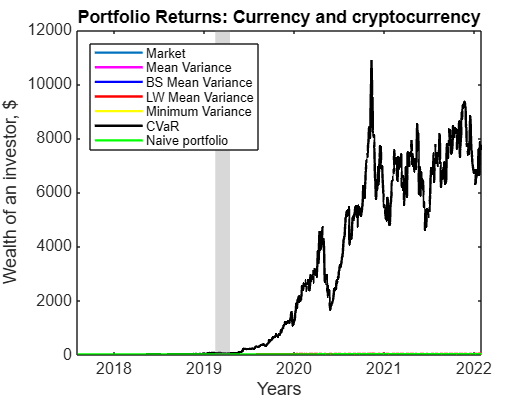

plot_comulative_returns(xData, r_benchmark, rp_currency_crypto, M, 'Currency and cryptocurrency');

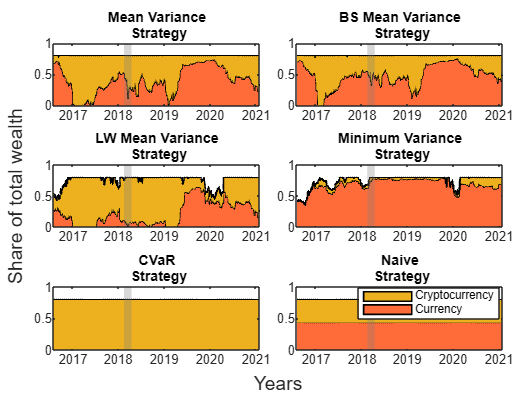

figure;
t = tiledlayout(3, 2, 'TileSpacing', 'Compact', 'Padding', 'Compact');
for p = 1:np
    y1 = sum(theta_currency_crypto(1:7,:,p), 1);
    y2 = sum(theta_currency_crypto(8:13,:,p), 1);
    nexttile
    area(xData(M+1:end), [y1; y2]', 'LineWidth', 1);
    hold on
    datetick('x','yyyy','keeplimits')
    recessionplot
    axis([xData(M+1) xData(end) -inf inf])
    colororder(['#FF6C3A'; '#EDB120'])
    xlabel(t, 'Years');
    ylabel(t, 'Share of total wealth')
    title([port_names(p), ' Strategy'])
end
legend('Currency', 'Cryptocurrency', 'Location', 'best')

#### Combining all three asset classes

theta_all_factors = calculate_theta(benchmark, factors, M, np, gam);
rp_all_factors = calculate_returns(benchmark, factors, theta_all_factors, M, np, trans_costs);
calculate_metrics(rp_all_factors);

-----Mean-variance portfolio-----
Mean = 0.543 
Std = 0.270 
Sharpe ratio = 2.015 
MDD = 0.339 
UI = 1.192 
Skewness = 0.308 
-----BS Mean-variance portfolio-----
Mean = 0.448 
Std = 0.250 
Sharpe ratio = 1.795 
MDD = 0.325 
UI = 1.338 
Skewness = -0.044 
-----LW Mean-variance portfolio-----
Mean = 0.774 
Std = 0.335 
Sharpe ratio = 2.310 
MDD = 0.372 
UI = 1.396 
Skewness = 1.690 
-----Minimum-variance portfolio-----
Mean = 0.133 
Std = 0.204 
Sharpe ratio = 0.653 
MDD = 0.285 
UI = 1.413 
Skewness = -0.755 
-----CVaR portfolio-----
Mean = 2.414 
Std = 0.918 
Sharpe ratio = 2.628 
MDD = 0.649 
UI = 3.685 
Skewness = 1.488 
-----1/N portfolio-----
Mean = 0.456 
Std = 0.253 
Sharpe ratio = 1.803 
MDD = 0.367 
UI = 0.993 
Skewness = -0.274 


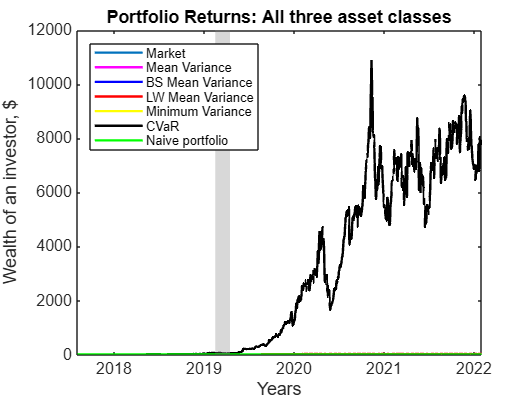

plot_comulative_returns(xData, r_benchmark, rp_all_factors, M, 'All three asset classes');

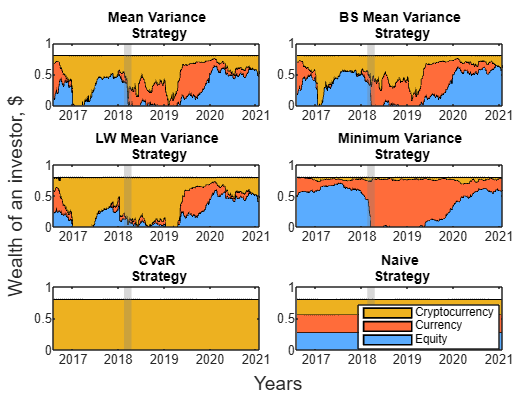

figure;
t = tiledlayout(3, 2, 'TileSpacing', 'Compact', 'Padding', 'Compact');
for p = 1:np
    y1 = sum(theta_all_factors(1:7,:,p), 1);
    y2 = sum(theta_all_factors(8:14,:,p), 1);
    y3 = sum(theta_all_factors(15:20,:,p), 1);
    nexttile
    area(xData(M+1:end), [y1; y2; y3]', 'LineWidth', 1);
    hold on
    datetick('x','yyyy','keeplimits')
    recessionplot
    axis([xData(M+1) xData(end) -inf inf])
    colororder(['#5AACFF'; '#FF6C3A'; '#EDB120'])
    xlabel(t, 'Years');
    ylabel(t, 'Wealth of an investor, $')
    title([port_names(p),' Strategy'])
end
legend('Equity', 'Currency', 'Cryptocurrency', 'Location', 'best')

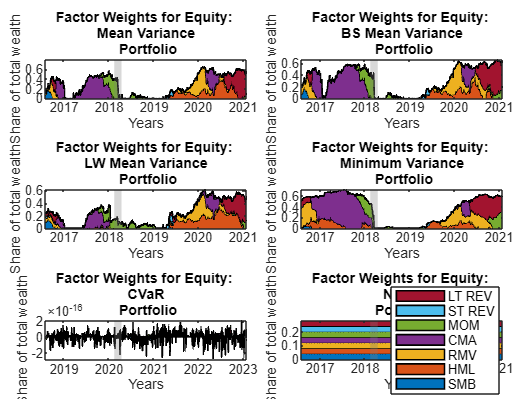

plot_factor_thetas(xData, equity_factor_names, port_names, ...
                       np, theta_all_factors(1:7,:,:), M, 'Factor Weights for Equity: ')

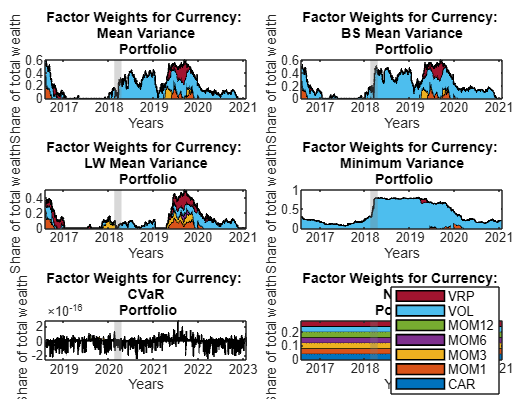

plot_factor_thetas(xData, currency_factor_names, port_names, ...
                       np, theta_all_factors(8:14,:,:), M, 'Factor Weights for Currency: ')

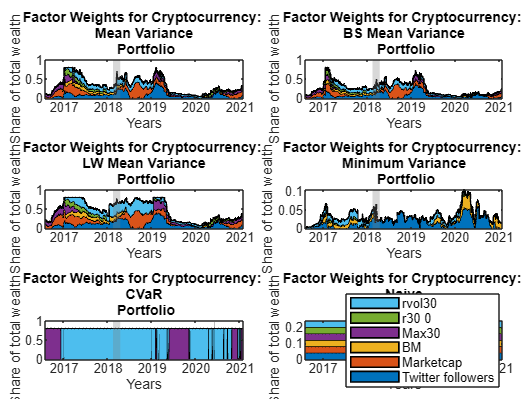

plot_factor_thetas(xData, crypto_factor_names, port_names, ...
                       np, theta_all_factors(15:20,:,:), M, 'Factor Weights for Cryptocurrency: ')

### Analysing Sharpe ratio dynamics

function sharpe_ratios = compute_SRs_dynamics(portfolio_returns, window_size, np)

    T = size(portfolio_returns, 1);
    sharpe_ratios = NaN(T-window_size, np);
    
    for i = 1:T-63
            
        t0  = i;
        t   = window_size + i - 1;
    
        rp_est = portfolio_returns(t0:t, :);
        
        rp_mean = mean(rp_est);
        rp_std  = std(rp_est);
        sharpe_ratios(i, :)  = (rp_mean ./ rp_std) * sqrt(window_size);
    
    end

end

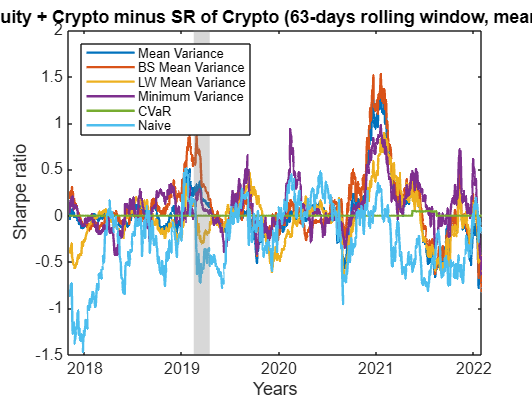

window_size = 63;   % Equivalent to 3 months
MV_crypto_SRs = compute_SRs_dynamics(rp_crypto, window_size, np);
MV_equity_and_crypto_SRs = compute_SRs_dynamics(rp_equity_crypto, window_size, np);

figure;
plot(xData(M+1+window_size:end), MV_equity_and_crypto_SRs - MV_crypto_SRs, 'LineWidth', 1.5);
hold on
datetick('x', 'yyyy', 'keeplimits')
recessionplot
axis([xData(M+1+window_size) xData(end) -inf inf])
xlabel('Years');
ylabel('Sharpe ratio')
title(append('SR of Equity + Crypto minus SR of Crypto (63-days rolling window, mean-variance)'))
legend(port_names, 'Location', 'Northwest', 'FontSize', 8)

### Saving results to xlsx files

function save_rp_to_xlsx(portfolio_returns, name, port_names, Date)

    rp_table = array2table(portfolio_returns, 'VariableNames', port_names);
    rp_table.Date = Date;
    rp_table = rp_table(:,[end 1:end-1]);
    filename = ['Returns/', name,' portfolios.xlsx'];
    writetable(rp_table, filename, 'Sheet', name);

end

function save_thetas_to_xlsx(portfolio_thetas, name, port_names, factor_names, np, Date)
    
    filename = ['Thetas/', name, ' thetas.xlsx'];

    for p = 1:np
        theta_table = array2table(portfolio_thetas(:,:,p)', 'VariableNames', factor_names);
        theta_table.Date = Date;
        theta_table = theta_table(:,[end 1:end-1]);
        sheetname = port_names{p};
        writetable(theta_table, filename, 'Sheet', sheetname);
    end

end

portfolio_returns = {rp_equity; rp_currency; rp_crypto;
                    rp_equity_currency; rp_equity_crypto; rp_currency_crypto; 
                    rp_all_factors};

portfolio_thetas = {theta_equity; theta_currency; theta_crypto;
                    theta_equity_currency; theta_equity_crypto; theta_currency_crypto;
                    theta_all_factors};

file_names = {'Equity'; 'Currency'; 'Cryptocurrency';
              'Equity and currency'; 'Equity and cryptocurrency'; 'Currency and cryptocurrency';
              'All three asset classes'};

for p = 1:size(portfolio_returns)
    save_rp_to_xlsx(portfolio_returns{p}, file_names{p}, port_names, Data20F.DATE(M+1:end));
end

factor_names = {equity_factor_names; currency_factor_names; crypto_factor_names;
                [equity_factor_names; currency_factor_names];
                [equity_factor_names; crypto_factor_names];
                [currency_factor_names; crypto_factor_names]
                [equity_factor_names; currency_factor_names; crypto_factor_names]};

for p = 1:size(portfolio_thetas)
    save_thetas_to_xlsx(portfolio_thetas{p}, file_names{p}, port_names, ...
                        factor_names{p}, np, Data20F.DATE(M+1:end));
end